#### Using estimation Data Level_3 and validation data Level_2 MISO)

`case: (1) where measurements are being taken at the excitation point location on the aircraft)`

clear;

ESTIM = load('F16Data_FullMSine_Level3.mat'); 
VALID = load('F16Data_FullMSine_Level2_Validation.mat'); 


% Parameters
N = length(ESTIM.Force); % Number of samples
Fs = ESTIM.Fs;           % Sampling frequency
Ts = 1/Fs;               % Sampling time

%iddata Objects for System Identification
% Estimation data 
% Force and Voltage as inputs
inputs = [ESTIM.Force; ESTIM.Voltage]';

% Acceleration in X, Y, Z as outputs
outputs = [ESTIM.Acceleration(1,:)]';

% iddata object
data_Estimation = iddata(outputs, inputs, Ts);

% Validation data
inputs_Val = [VALID.Force; VALID.Voltage]';
outputs_Val = [VALID.Acceleration(1,:)]';

data_Validation = iddata(outputs_Val, inputs_Val, Ts);
%systemIdentification

**Define Models**

arx221 = arx(data_Estimation,[2,[2 2], [1 1]], arxOptions); % Initial Model
arx661 = arx(data_Estimation,[6,[6 6], [1 1]], arxOptions); % Improved Model
arx771 = arx(data_Estimation,[7,[7 7], [1 1]], arxOptions); % Improved Model
oe441 = oe(data_Estimation,[[4 4],[4 4], [1 1]], oeOptions); % Improved Model

**Define Predictions and Simulations**

y_pred = predict(arx661, data_Validation, 1);
y_sim221 = sim(arx221, data_Validation.InputData);
y_sim771 = sim(arx771, data_Validation.InputData);
y_sim441 = sim(oe441, data_Validation.InputData);

### First Model ARX221

**Evaluate Against Validation Data**

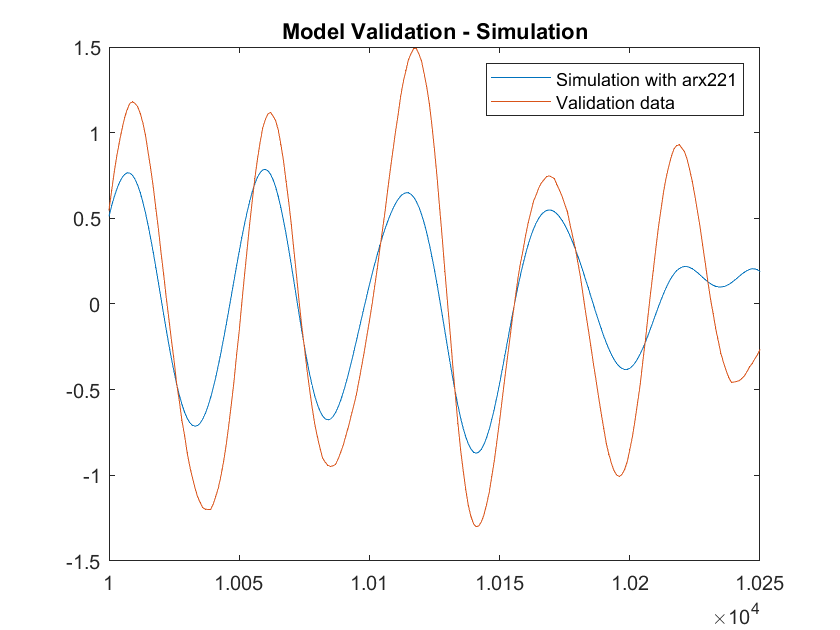

[~, fit, ~] = compare(data_Validation, arx221);
figure;
plot(y_sim221)
hold on
plot(data_Validation.OutputData)
legend('Simulation with arx221', 'Validation data')
xlim([10000 10250])
title('Model Validation - Simulation')

disp(['Fit Percentage: ', num2str(fit), '%']);

Fit Percentage: 10.7011%


**First Impresion From Plot**

From the plot above we can clearly see that the arx221 model does not preform well when compared to the validation data. We can assume that the model needs to be higher order in order to increase the gain. However it looks like the model neither leads or lags the validation data so the time delay looks to be alright. All this ofcourse results in a low percentage of fit (10.7%).

**Residue Analysis**

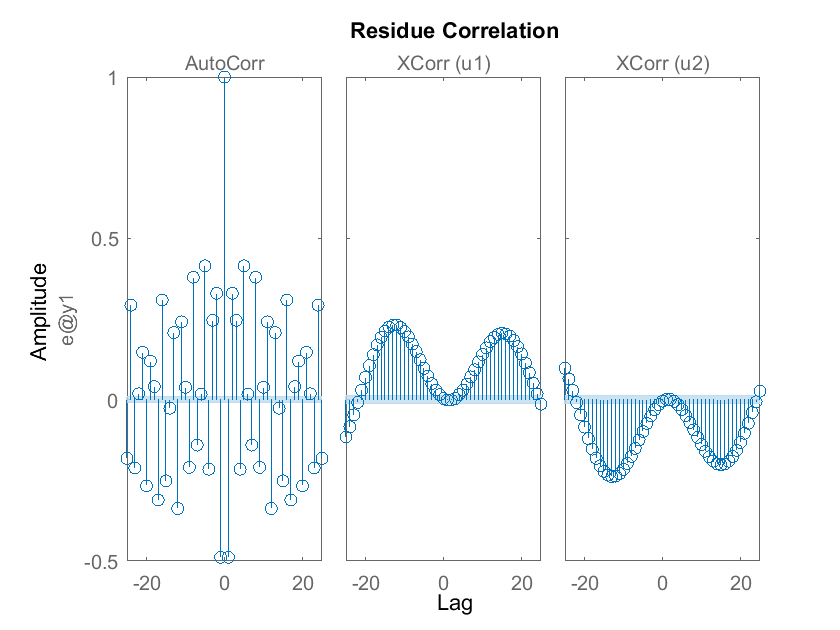

figure;
resid(data_Validation, arx221, 'corr')

Here when can clearly see in both the outocorrelation and in the crosscorrelation that values are well outside the coinfidence region which tells us that the residuals are not white noise and that our model does not capture the system dynamics well.

### Second Model ARX771

**Evaluate Against Validation Data**

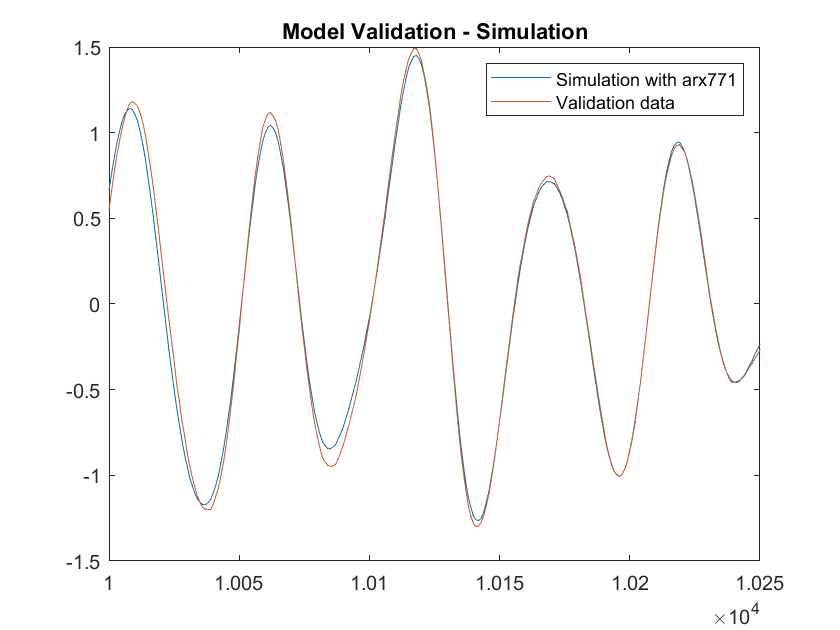

[~, fit, ~] = compare(data_Validation, arx771);
figure;
plot(y_sim771)
hold on
plot(data_Validation.OutputData)
legend('Simulation with arx771', 'Validation data')
xlim([10000 10250])
title('Model Validation - Simulation')

disp(['Fit Percentage: ', num2str(fit), '%']);

Fit Percentage: 81.31%


**First Impressions From Plot**

Now the model looks better, we can see that there is some diffrence from the validation still. The fit is now quite good at 81.33%. This was the highest model order that did not overfit!

**Residue analysis**

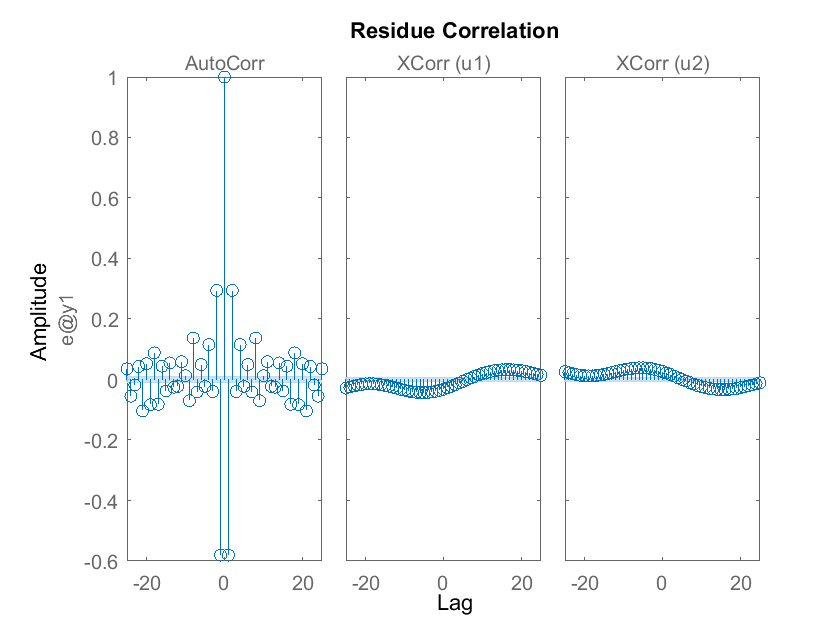

figure;
resid(data_Validation, arx771, 'corr')

Here we can see that the crosscorelation has improved dramatically! However the autocorrelation is still not good. Considering that this was the highest order possible without overfitting we can probably say that model order is not the issue. It is more probable that ARX models can not completely capture the dynamics of this system, or the noise is not completely white. Let's try an OE-Model. 

### Third Model

**Evaluate Against Validation Data**

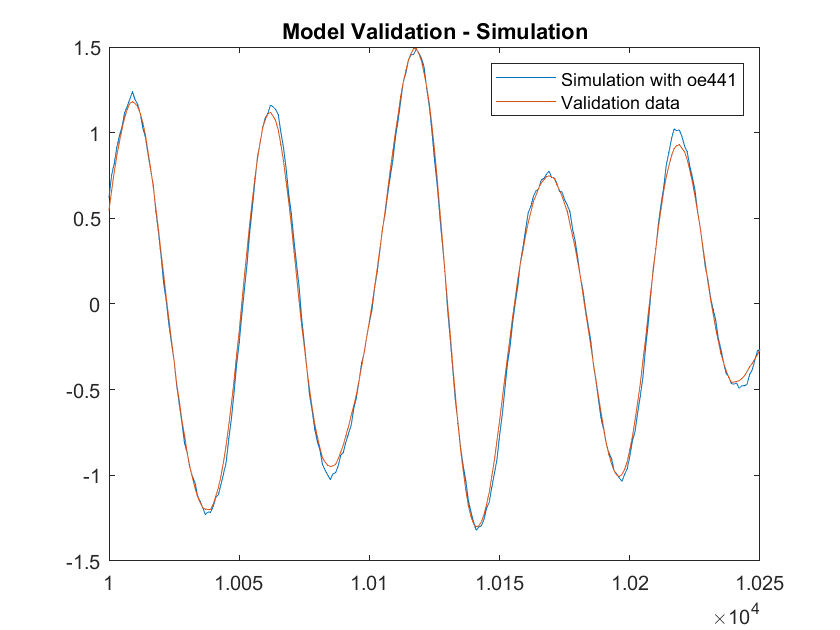

[~, fit, ~] = compare(data_Validation, oe441);
figure;
plot(y_sim441)
hold on
plot(data_Validation.OutputData)
legend('Simulation with oe441', 'Validation data')
xlim([10000 10250])
title('Model Validation - Simulation')

disp(['Fit Percentage: ', num2str(fit), '%']);

Fit Percentage: 88.3417%


**First Impression From Plot**

The plot looks good, the model is possibly overfitting a bit(?). The percentage of fit (88%) is higher than the ARX-Models!

**Residue Analysis**

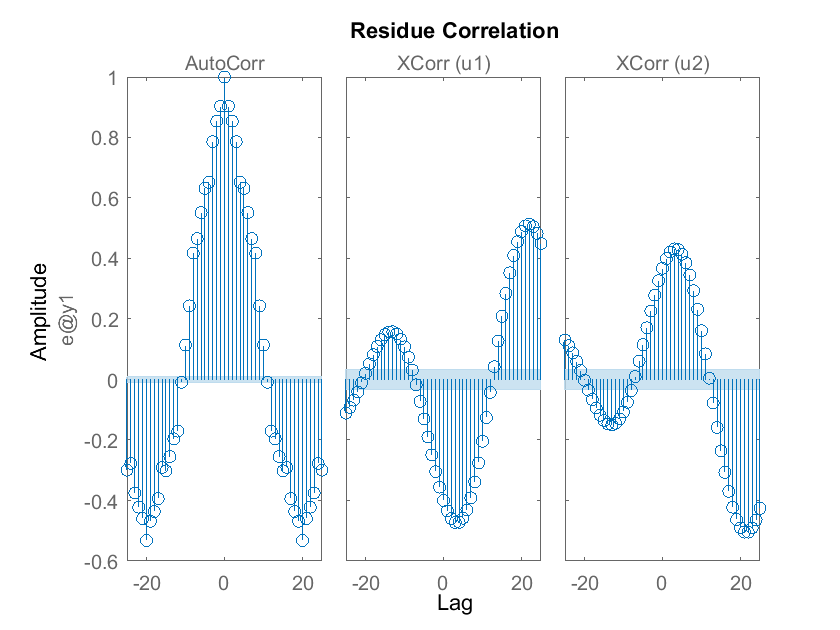

figure;
resid(data_Validation, oe441, 'corr')

Even though the percentange fit was higher for the OE model, when looking at the residue analysis, we can see that the model is not good. There is significant spikes in the both the crosscorrelation and the autocorrelation. This shows that the OE model does not capture the dynamics of the system well. (This holds true for many, maybe all OE models.) The high precentage of fit can be attributed to overfitting. Thus we can (maybe) say that the ARX-Models preform better????